# Offline RL for GBWM — Week 6.0b: Extended Train (2010-2021) + Plan C reward

Week 6.0 result: oversampling alone raised mean Sharpe but doubled MaxDD P90 (11.79% -> 18.04%). Diagnosis: 2010-2019 train data contains no persistent stress regime (no GFC, no COVID); every "stress day" in that window is a short V-shaped panic that recovered fast. Oversampling those days taught the agent "stress = buy-the-dip" — exactly the opposite of what test 2022 (12-month persistent stock-bond crash) rewards.

Week 6.0b fixes the data, not the algorithm. The previously-unused val split (2020-2021) is merged into train via scripts/merge_train_val.py. The COVID 2020 crash + 2021 rate-suppression era is the closest analogue we have to the test regime.

New train: 2010-01 -> 2021-12 (3020 trading days after diff(log), was 2515) Test: 2022-01 -> 2025-12 (UNCHANGED, no leakage)

Two-stage protocol on this extended dataset: Stage 1 (this file, USE_OVERSAMPLING=false): uniform sampling -> isolates the contribution of new data alone. Stage 2 (rerun this file with USE_OVERSAMPLING=true): add back the stress-window oversampling -> measures incremental contribution.

Reward (Plan C, unchanged): peakW(t) := max(peakW(t-1), W_{t+1}) DD(t) := (peakW(t) - W_{t+1}) / peakW(t) r(t) := log(W_{t+1}/W_t) - beta * max(0, DD(t) - DD_THR) r(T) += 1.0 if W_T >= goalWealth

clear; clc;

## Fixed Parameters

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 3020;        % NEW: was 2515 (extended by COVID + 2021)
horizonPeriods  = 30;
numEpisodes     = 200;         % NEW: was 165 (more episodes to use new data)
numActions      = 15;

logsRoot        = fullfile("experiments", "logs", "week6_0b_extended_train");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

seeds           = [1000 2000 3000 4000 5000];
nSeeds          = numel(seeds);

numEvalEpisodes = 30;
evalStepSize    = 30;

% Plan C reward (unchanged)
BETA   = 5.0;
DD_THR = 0.03;

% Stage toggle: false = uniform sampling (isolate data effect),
%               true  = stress-window oversampling on top
USE_OVERSAMPLING = true;
EPSILON_WEIGHT   = 0.5;   % only used when USE_OVERSAMPLING = true

% Macro column indices in z-scored matrix [DGS10_z, T10Y2Y_z, VIXCLS_z, DFF_z]
COL_T10Y2Y = 2;
COL_VIX    = 3;

## Load EXTENDED price data

pricesTT   = readtable("data/prices_train_extended.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);
P_train    = pricesTT{:, 2:end};
R_train    = diff(log(P_train));

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

## Load EXTENDED macro data, z-score on extended train

macroTT   = readtable("data/macro_train_extended.csv");
M_train   = macroTT{:, 2:end};
macroMean = mean(M_train, 1);
macroStd  = std(M_train, 0, 1);
macroStd(macroStd == 0) = 1;
M_train_z = (M_train - macroMean) ./ macroStd;

## Load + z-score test data (UNCHANGED test files)

[R_full, M_test_z] = inputTestData('data/prices_test.csv', 'data/macro_test.csv', ...
                                    macroMean, macroStd);

## --- Stress-day diagnostic + (optional) weighted start distribution ---

stressScoreDay = max(0, M_train_z(:, COL_VIX)) + max(0, -M_train_z(:, COL_T10Y2Y));

isStressDay_train = (M_train_z(:, COL_VIX) > 1.5) | (M_train_z(:, COL_T10Y2Y) < -1.5);
trainStressRateBaseline = mean(isStressDay_train(1:trainingRange));
isStressDay_test  = (M_test_z(:, COL_VIX) > 1.5) | (M_test_z(:, COL_T10Y2Y) < -1.5);
testStressRate    = mean(isStressDay_test);

candStarts = (1 : (trainingRange - horizonPeriods + 1))';
assert(max(candStarts) + horizonPeriods - 1 <= trainingRange, ...
    "candidate start range overflows train segment");

if USE_OVERSAMPLING
    windowWeights = zeros(numel(candStarts), 1);
    for k = 1:numel(candStarts)
        s = candStarts(k);
        windowWeights(k) = sum(stressScoreDay(s : s + horizonPeriods - 1));
    end
    windowWeights = windowWeights + EPSILON_WEIGHT;
else
    windowWeights = [];   % unused
end

fprintf("=== Stress-day diagnostics (extended train: 2010-2021) ===\n");

=== Stress-day diagnostics (extended train: 2010-2021) ===


fprintf("  Train stress rate (uniform-sample proxy) : %.1f%%\n", ...
    100 * trainStressRateBaseline);

  Train stress rate (uniform-sample proxy) : 11.0%


fprintf("  Test  stress rate (target)               : %.1f%%\n", ...
    100 * testStressRate);

  Test  stress rate (target)               : 67.7%


fprintf("  USE_OVERSAMPLING                         : %s\n", ...
    string(USE_OVERSAMPLING));

  USE_OVERSAMPLING                         : true


if USE_OVERSAMPLING
    fprintf("  Oversampling epsilon                     : %.2f\n", EPSILON_WEIGHT);
end

  Oversampling epsilon                     : 0.50


## Cross-seed result storage

results = struct();
results.successRate     = nan(nSeeds, 1);
results.meanSharpe      = nan(nSeeds, 1);
results.stdSharpe       = nan(nSeeds, 1);
results.meanMaxDD       = nan(nSeeds, 1);
results.stdMaxDD        = nan(nSeeds, 1);
results.meanTermWealth  = nan(nSeeds, 1);
results.p10TermWealth   = nan(nSeeds, 1);
results.p90TermWealth   = nan(nSeeds, 1);
results.minSharpe       = nan(nSeeds, 1);
results.p90MaxDD        = nan(nSeeds, 1);
results.actionHist      = zeros(nSeeds, numActions);
results.penaltyShare    = nan(nSeeds, 1);
results.meanPenalty     = nan(nSeeds, 1);
results.trainStressRate = nan(nSeeds, 1);

allWealthPathsBySeed = cell(nSeeds, 1);

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

obsDim = 2 + size(M_train_z, 2);

## Loop over seeds

for sIdx = 1:nSeeds
    seed = seeds(sIdx);
    rng(seed, "twister");

    fprintf("\n========== Seed %d (%d/%d) ==========\n", seed, sIdx, nSeeds);

    seedLogsFolder = fullfile(logsRoot, sprintf("seed_%d", seed));
    if isfolder(seedLogsFolder)
        delete(fullfile(seedLogsFolder, "*.mat"));
    else
        mkdir(seedLogsFolder);
    end

    % --- Episode start sampling ---
    if USE_OVERSAMPLING
        sampledStarts = randsample(candStarts, numEpisodes, true, windowWeights);
    else
        % Uniform sliding window (matches original Plan C protocol but over
        % the extended range): step = floor(trainingRange / numEpisodes) to
        % spread starts evenly. Use replacement-free sampling.
        stepSize      = max(1, floor((trainingRange - horizonPeriods) / numEpisodes));
        sampledStarts = (1 + (0:numEpisodes-1)' * stepSize);
        sampledStarts = sampledStarts(sampledStarts + horizonPeriods - 1 <= trainingRange);
        if numel(sampledStarts) < numEpisodes
            warning("Only %d episodes fit; reducing numEpisodes for this seed.", ...
                numel(sampledStarts));
        end
    end
    nEpThisSeed = numel(sampledStarts);

    % --- Build offline episodes with Plan C reward ---
    nPenaltySteps     = 0;
    penaltySum        = 0;
    nStressStepsSeen  = 0;
    nTotalStepsSeen   = 0;

    for episodeCount = 1:nEpThisSeed
        startIdx  = sampledStarts(episodeCount);
        expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
            "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

        wealth = initialWealth;
        peakW  = initialWealth;

        for t = 1:horizonPeriods
            dayIdx   = startIdx + t - 1;
            macroVec = M_train_z(dayIdx, :)';
            obs      = [normalizeWealth(wealth); timeFrac(t); macroVec];

            aIdx = randi(numActions);
            w    = W_frontier(:, aIdx);

            r_tp1      = R_sub(dayIdx, :) * w;
            wealthNext = (wealth + contribution) * (1 + r_tp1);

            peakW   = max(peakW, wealthNext);
            DD_t    = (peakW - wealthNext) / peakW;
            penalty = BETA * max(0, DD_t - DD_THR);
            reward  = log(wealthNext / wealth) - penalty;

            if penalty > 0
                nPenaltySteps = nPenaltySteps + 1;
                penaltySum    = penaltySum + penalty;
            end

            nStressStepsSeen = nStressStepsSeen + double(isStressDay_train(dayIdx));
            nTotalStepsSeen  = nTotalStepsSeen + 1;

            if t == horizonPeriods && wealthNext >= goalWealth
                reward = reward + 1.0;
            end

            nextDayIdx   = min(dayIdx + 1, size(M_train_z, 1));
            nextMacroVec = M_train_z(nextDayIdx, :)';
            nextObs      = [normalizeWealth(wealthNext); ...
                            timeFrac(min(t+1, horizonPeriods)); ...
                            nextMacroVec];
            isDone       = (t == horizonPeriods);

            expStruct(t).Observation     = {obs};
            expStruct(t).Action          = {aIdx};
            expStruct(t).Reward          = reward;
            expStruct(t).NextObservation = {nextObs};
            expStruct(t).IsDone          = isDone;

            wealth = wealthNext;
        end

        epFile = fullfile(seedLogsFolder, sprintf("loggedData%03d.mat", episodeCount));
        exp = expStruct;
        save(epFile, "exp");
    end

    totalSteps = nEpThisSeed * horizonPeriods;
    results.penaltyShare(sIdx)    = nPenaltySteps / totalSteps;
    results.trainStressRate(sIdx) = nStressStepsSeen / nTotalStepsSeen;
    if nPenaltySteps > 0
        results.meanPenalty(sIdx) = penaltySum / nPenaltySteps;
    else
        results.meanPenalty(sIdx) = 0;
    end
    fprintf("  Saved %d episodes (%d steps). Stress-day share: %.1f%% (baseline %.1f%%, test %.1f%%)\n", ...
        nEpThisSeed, totalSteps, 100*results.trainStressRate(sIdx), ...
        100*trainStressRateBaseline, 100*testStressRate);
    fprintf("  Penalty-active steps: %d (%.1f%%), avg magnitude %.4f\n", ...
        nPenaltySteps, 100*results.penaltyShare(sIdx), results.meanPenalty(sIdx));

    % --- File datastore ---
    myReadFcn = @(fname) load(fname, "exp").exp;
    fds = fileDatastore(fullfile(seedLogsFolder, "loggedData*.mat"), ...
                        "ReadFcn", myReadFcn);

    % --- Build fresh agent ---
    obsInfo = rlNumericSpec([obsDim 1], Name="GBWMObservation");
    actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

    criticLG = layerGraph([
        featureInputLayer(obsInfo.Dimension(1), Name="state")
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(numActions, Name="Qout")
        ]);

    criticNet = dlnetwork(criticLG);
    critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

    agentOpts = rlDQNAgentOptions( ...
        DiscountFactor=discountFactor, ...
        ExperienceBufferLength=1e6, ...
        MiniBatchSize=miniBatchSize, ...
        TargetUpdateMethod="periodic", ...
        TargetUpdateFrequency=4, ...
        UseDoubleDQN=true);
    agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
    agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
    agent = rlDQNAgent(critic, agentOpts);

    % --- Train ---
    tfdOpts = rlTrainingFromDataOptions( ...
        MaxEpochs        = maxEpochs, ...
        NumStepsPerEpoch = stepsPerEpoch, ...
        Plots            = "none", ...
        Verbose          = false);
    trainFromData(agent, fds, tfdOpts);
    save(fullfile(seedLogsFolder, "TrainedAgent.mat"), "agent");

    % --- Hold-out evaluation ---
    successCount   = 0;
    allSharpes     = nan(numEvalEpisodes, 1);
    allMaxDD       = nan(numEvalEpisodes, 1);
    allTermWealth  = nan(numEvalEpisodes, 1);
    allWealthPaths = cell(numEvalEpisodes, 1);
    allActions     = zeros(numEvalEpisodes, horizonPeriods);

    for ep = 1:numEvalEpisodes
        startEval = (ep-1)*evalStepSize + 1;
        if startEval + horizonPeriods - 1 > size(R_full, 1)
            break;
        end

        wealth = zeros(horizonPeriods+1, 1);
        wealth(1) = initialWealth;
        chosenActions = zeros(1, horizonPeriods);
        for t = 1:horizonPeriods
            dayIdx   = startEval + t - 1;
            macroVec = M_test_z(dayIdx, :)';
            obs      = { [normalizeWealth(wealth(t)); timeFrac(t); macroVec] };
            aGreedy  = agent.getAction(obs);
            chosenActions(t) = aGreedy{1};
            w        = W_frontier(:, aGreedy{1});
            r_tp1    = R_full(dayIdx, :) * w;
            wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
        end

        rets    = diff(log(wealth));
        sharpe  = mean(rets) / std(rets) * sqrt(252);
        maxDD   = max(cummax(wealth) - wealth) / max(wealth);

        allSharpes(ep)     = sharpe;
        allMaxDD(ep)       = maxDD;
        allTermWealth(ep)  = wealth(end);
        allWealthPaths{ep} = wealth;
        allActions(ep, :)  = chosenActions;
        successCount       = successCount + double(wealth(end) >= goalWealth);
    end

    results.successRate(sIdx)    = successCount;
    results.meanSharpe(sIdx)     = mean(allSharpes,'omitnan');
    results.stdSharpe(sIdx)      = std(allSharpes,'omitnan');
    results.meanMaxDD(sIdx)      = mean(allMaxDD,'omitnan');
    results.stdMaxDD(sIdx)       = std(allMaxDD,'omitnan');
    results.meanTermWealth(sIdx) = mean(allTermWealth,'omitnan');
    results.p10TermWealth(sIdx)  = prctile(allTermWealth, 10);
    results.p90TermWealth(sIdx)  = prctile(allTermWealth, 90);
    results.minSharpe(sIdx)      = min(allSharpes);
    results.p90MaxDD(sIdx)       = prctile(allMaxDD, 90);
    for a = 1:numActions
        results.actionHist(sIdx, a) = sum(allActions(:) == a);
    end

    allWealthPathsBySeed{sIdx} = allWealthPaths;

    fprintf("  Success %d/%d | Sharpe %.2f±%.2f | MaxDD %.2f%%±%.2f%% | TermW %.0f (P10 %.0f)\n", ...
        successCount, numEvalEpisodes, ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end


========== Seed 1000 (1/5) ==========


  Saved 200 episodes (6000 steps). Stress-day share: 32.4% (baseline 11.0%, test 67.7%)


  Penalty-active steps: 2099 (35.0%), avg magnitude 0.2570


  Success 16/30 | Sharpe 1.01±3.23 | MaxDD 13.80%±7.75% | TermW 106473 (P10 86048)



========== Seed 2000 (2/5) ==========


  Saved 200 episodes (6000 steps). Stress-day share: 39.2% (baseline 11.0%, test 67.7%)


  Penalty-active steps: 1903 (31.7%), avg magnitude 0.2429


  Success 12/30 | Sharpe 0.66±2.85 | MaxDD 10.49%±5.62% | TermW 102861 (P10 91172)



========== Seed 3000 (3/5) ==========


  Saved 200 episodes (6000 steps). Stress-day share: 36.8% (baseline 11.0%, test 67.7%)


  Penalty-active steps: 2052 (34.2%), avg magnitude 0.2723


  Success 17/30 | Sharpe 0.71±3.01 | MaxDD 8.41%±4.93% | TermW 103890 (P10 89957)



========== Seed 4000 (4/5) ==========


  Saved 200 episodes (6000 steps). Stress-day share: 30.9% (baseline 11.0%, test 67.7%)


  Penalty-active steps: 1976 (32.9%), avg magnitude 0.2791


  Success 11/30 | Sharpe -0.34±3.18 | MaxDD 6.53%±5.34% | TermW 98372 (P10 89002)



========== Seed 5000 (5/5) ==========


  Saved 200 episodes (6000 steps). Stress-day share: 37.1% (baseline 11.0%, test 67.7%)


  Penalty-active steps: 1898 (31.6%), avg magnitude 0.2832


  Success 15/30 | Sharpe 0.51±3.14 | MaxDD 8.33%±8.04% | TermW 99754 (P10 86176)


## Cross-seed summary

fprintf("\n\n===== Cross-seed summary (n=%d seeds) — Week 6.0b extended train (2010-2021) =====\n", nSeeds);



===== Cross-seed summary (n=5 seeds) — Week 6.0b extended train (2010-2021) =====


fprintf("Train range             : 2010-01 -> 2021-12  (%d trading days, was 2515)\n", trainingRange);

Train range             : 2010-01 -> 2021-12  (3020 trading days, was 2515)


fprintf("USE_OVERSAMPLING        : %s\n", string(USE_OVERSAMPLING));

USE_OVERSAMPLING        : true


fprintf("Reward shaping          : BETA = %.2f   DD_THR = %.3f   (Plan C, unchanged)\n", BETA, DD_THR);

Reward shaping          : BETA = 5.00   DD_THR = 0.030   (Plan C, unchanged)


fprintf("Train stress occupation : %.1f%% (avg)   baseline %.1f%%   test target %.1f%%\n", ...
    100*mean(results.trainStressRate), 100*trainStressRateBaseline, 100*testStressRate);

Train stress occupation : 35.3% (avg)   baseline 11.0%   test target 67.7%


fprintf("Penalty-active share    : %.1f%% of training steps (avg)\n", ...
    100*mean(results.penaltyShare));

Penalty-active share    : 33.1% of training steps (avg)


fprintf("Success rate            : %.1f / %d  (std %.2f)\n", ...
    mean(results.successRate), numEvalEpisodes, std(results.successRate));

Success rate            : 14.2 / 30  (std 2.59)


fprintf("Mean Sharpe             : %.2f (across-seed std %.2f)\n", ...
    mean(results.meanSharpe), std(results.meanSharpe));

Mean Sharpe             : 0.51 (across-seed std 0.51)


fprintf("Within-seed Sharpe std  : %.2f (avg)\n", mean(results.stdSharpe));

Within-seed Sharpe std  : 3.08 (avg)


fprintf("Mean MaxDD              : %.2f%% (across-seed std %.2f%%)\n", ...
    mean(results.meanMaxDD)*100, std(results.meanMaxDD)*100);

Mean MaxDD              : 9.51% (across-seed std 2.78%)


fprintf("Mean Terminal Wealth    : %.0f (across-seed std %.0f)\n", ...
    mean(results.meanTermWealth), std(results.meanTermWealth));

Mean Terminal Wealth    : 102270 (across-seed std 3247)


fprintf("Terminal P10 (avg)      : %.0f\n", mean(results.p10TermWealth));

Terminal P10 (avg)      : 88471


fprintf("Worst Sharpe (avg)      : %.2f   <-- Plan C: -5.38 | 6.0: -5.31\n", ...
    mean(results.minSharpe));

Worst Sharpe (avg)      : -5.99   <-- Plan C: -5.38 | 6.0: -5.31


fprintf("MaxDD P90 (avg)         : %.2f%% <-- Plan C: 11.79%% | 6.0: 18.04%%\n", ...
    mean(results.p90MaxDD)*100);

MaxDD P90 (avg)         : 17.98% <-- Plan C: 11.79% | 6.0: 18.04%



fprintf("\n--- Per-seed table ---\n");


--- Per-seed table ---


fprintf("seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10) | stress%%\n");

seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10) | stress%


for sIdx = 1:nSeeds
    fprintf("%4d | %4d | %5.2f ± %4.2f    | %5.2f%% ± %4.2f%%  | %.0f / %.0f | %.1f%%\n", ...
        seeds(sIdx), results.successRate(sIdx), ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx), ...
        100*results.trainStressRate(sIdx));
end

1000 |   16 |  1.01 ± 3.23    | 13.80% ± 7.75%  | 106473 / 86048 | 32.4%
2000 |   12 |  0.66 ± 2.85    | 10.49% ± 5.62%  | 102861 / 91172 | 39.2%
3000 |   17 |  0.71 ± 3.01    |  8.41% ± 4.93%  | 103890 / 89957 | 36.8%
4000 |   11 | -0.34 ± 3.18    |  6.53% ± 5.34%  | 98372 / 89002 | 30.9%
5000 |   15 |  0.51 ± 3.14    |  8.33% ± 8.04%  | 99754 / 86176 | 37.1%



fprintf("\n--- Action histogram (all eval steps) ---\n");


--- Action histogram (all eval steps) ---


totalHist = sum(results.actionHist, 1);
totalSteps = sum(totalHist);
for a = 1:numActions
    if totalHist(a) > 0
        fprintf("  action %2d : %4d (%.1f%%)\n", a, totalHist(a), 100*totalHist(a)/totalSteps);
    end
end

  action  1 :  181 (4.0%)
  action  2 :  134 (3.0%)
  action  3 :  822 (18.3%)
  action  4 :   90 (2.0%)
  action  5 :  138 (3.1%)
  action  6 :   80 (1.8%)
  action  7 :   38 (0.8%)
  action  8 :  108 (2.4%)
  action  9 :  203 (4.5%)
  action 10 :  563 (12.5%)
  action 11 :   56 (1.2%)
  action 12 :   35 (0.8%)
  action 13 :  125 (2.8%)
  action 14 : 1048 (23.3%)
  action 15 :  879 (19.5%)


## Plot — aggregated wealth band across all seeds

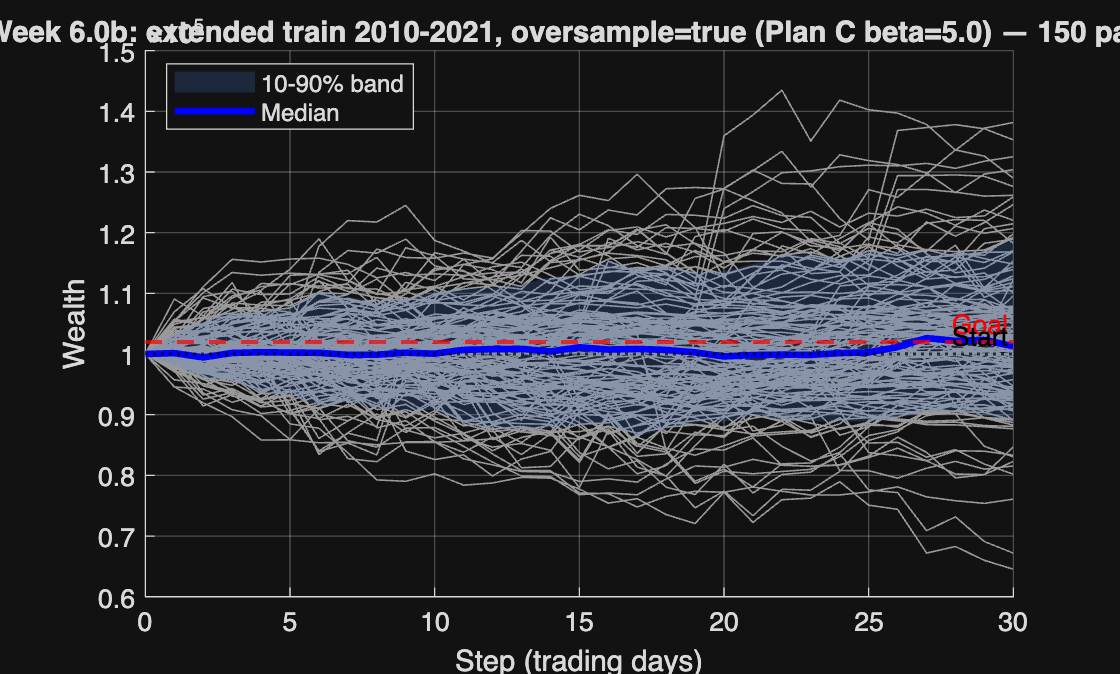

figName = sprintf('Hold-out wealth paths (Week 6.0b extended train, oversample=%s)', ...
    string(USE_OVERSAMPLING));
figure('Name', figName);
hold on;

allPathsFlat = nan(nSeeds * numEvalEpisodes, horizonPeriods + 1);
rowCursor = 0;
for sIdx = 1:nSeeds
    paths = allWealthPathsBySeed{sIdx};
    for ep = 1:numel(paths)
        if ~isempty(paths{ep})
            rowCursor = rowCursor + 1;
            allPathsFlat(rowCursor, :) = paths{ep}';
        end
    end
end
allPathsFlat = allPathsFlat(1:rowCursor, :);

steps = 0:horizonPeriods;

for r = 1:size(allPathsFlat, 1)
    plot(steps, allPathsFlat(r, :), 'Color', [0.6 0.6 0.6 0.15], ...
        'LineWidth', 0.6, 'HandleVisibility', 'off');
end

p10 = prctile(allPathsFlat, 10, 1);
p90 = prctile(allPathsFlat, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');
plot(steps, median(allPathsFlat, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Week 6.0b: extended train 2010-2021, oversample=%s (Plan C beta=%.1f) — %d paths', ...
    string(USE_OVERSAMPLING), BETA, rowCursor));
legend('Location','best');
grid on;

## Local Functions

function [R, M_z] = inputTestData(priceFile, macroFile, macroMean, macroStd)
    pricesTT = readtable(priceFile, 'VariableNamingRule', 'preserve');
    P = pricesTT{:, 2:end};
    R = diff(log(P));

    macroTT = readtable(macroFile, 'VariableNamingRule', 'preserve');
    M = macroTT{:, 2:end};
    M_z = (M - macroMean) ./ macroStd;
end